# Equlibrium analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
%Prefix = '2020-11-21-optoknirps_eve4_6_embryo5';
%Prefix = '2020-11-22-optoknirps_eve4_6_embryo6';
%Prefix = '2020-11-24-optoknirps_eve4_6_embryo7';
Prefix = '2020-11-27-optoknirps_eve4_6_embryo8';


Initialize some parameters

minAP = 0.4;
maxAP = 0.8;

maxT = 40;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/' Prefix];

mkdir(FigPath)
% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to CompiledParticles
LoadParticlePath = [DynamicsResultsFolder '/' Prefix '/CompiledParticles.mat']; 
%LoadNucleiPath = [DynamicsResultsFolder '/' Prefix '/' Prefix '_lin.mat'];
LoadComNucleiPath = [DynamicsResultsFolder '/' Prefix '/CompiledNuclei.mat']; 

data.particle = load(LoadParticlePath);
data.nuclei = load(LoadComNucleiPath);
%load(LoadNucleiPath)

ElapsedTime = data.particle.ElapsedTime;
start_frame = data.nuclei.nc14;
final_frame = length(ElapsedTime);

ElapsedTime = data.particle.ElapsedTime-data.particle.ElapsedTime(start_frame);
Time = ElapsedTime(start_frame:final_frame);
APbinID = data.particle.APbinID;

## Part 2: Draw figures 

### For particles

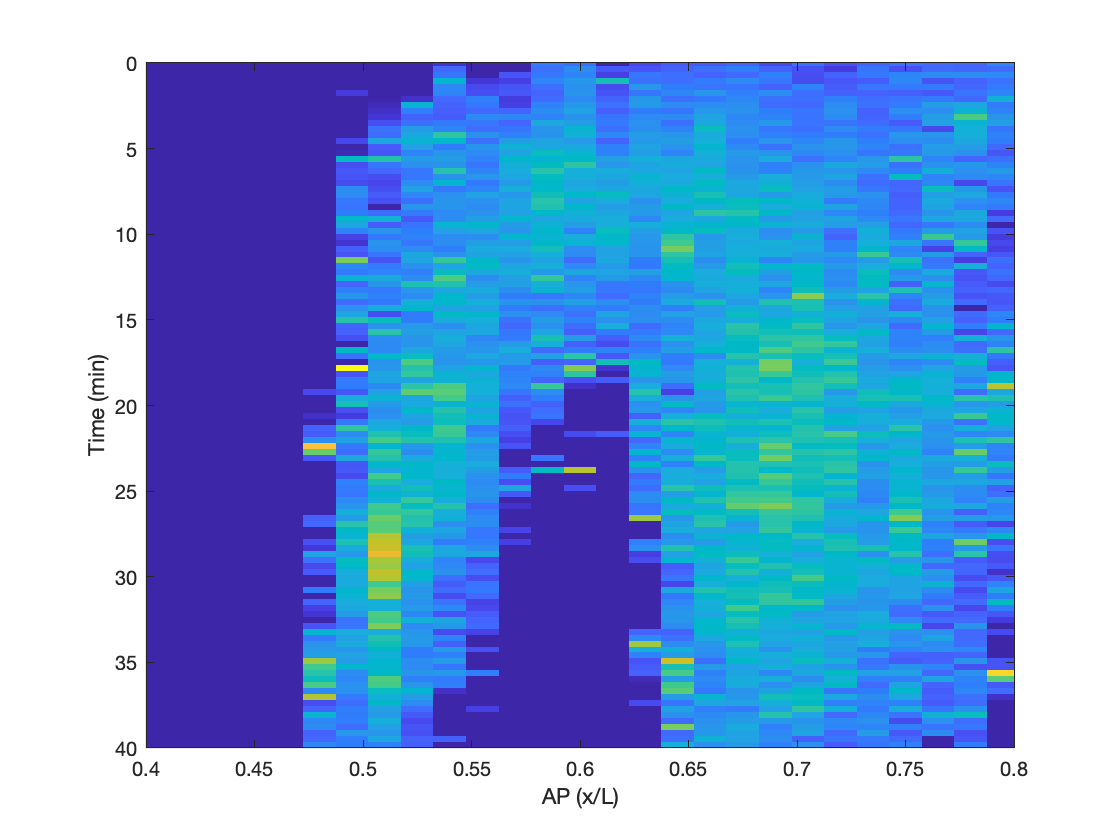

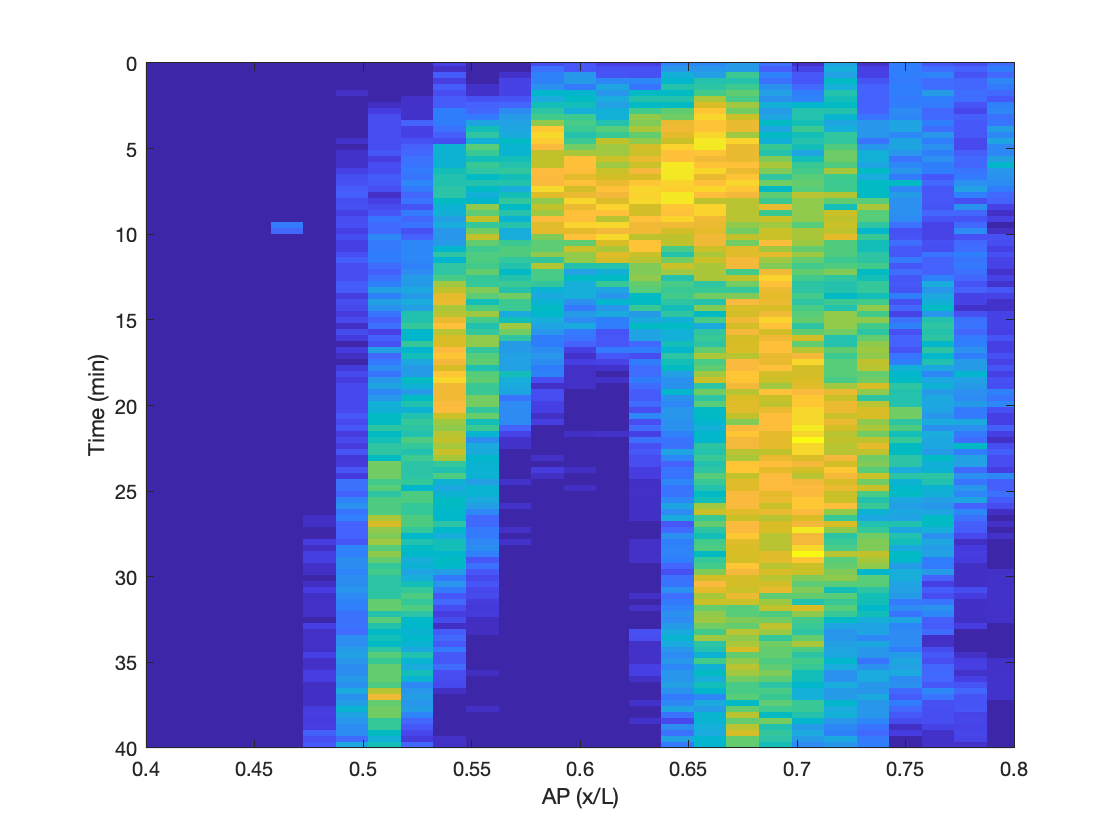

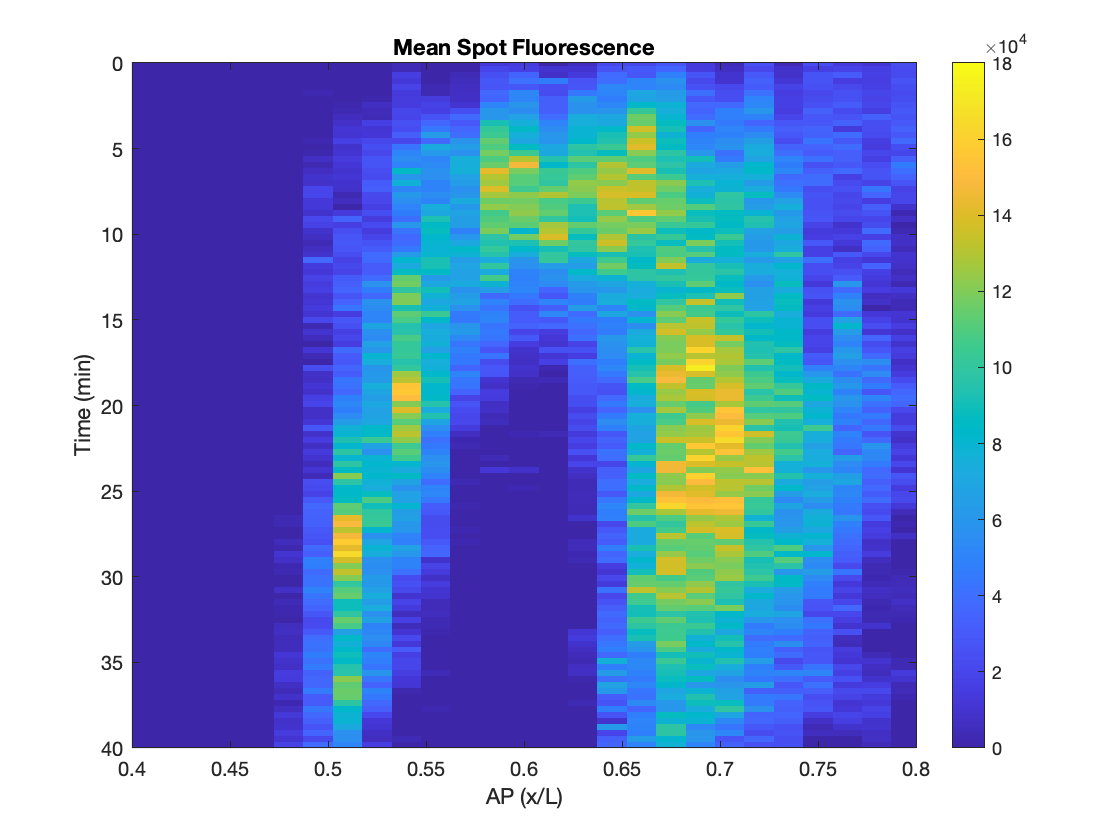

% Plot mean vector
MeanFig = figure;
imagesc(APbinID,Time,data.particle.MeanVectorAP{1}(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 maxT])
% Plot fraction on
OnFig = figure;
imagesc(APbinID,Time,data.particle.OnRatioAP{1}(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 maxT])

% Plot mean vector (all nuclei)
data_plot = data.particle.OnRatioAP{1}.*data.particle.MeanVectorAP{1};

MeanAllFig = figure;
imagesc(APbinID,Time,data_plot(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 maxT])
title('Mean Spot Fluorescence')
colorbar
caxis([0 1.8E5])
saveas(MeanAllFig,[FigPath '/MeanSpot_fluo.pdf' ]);

### For nuclei

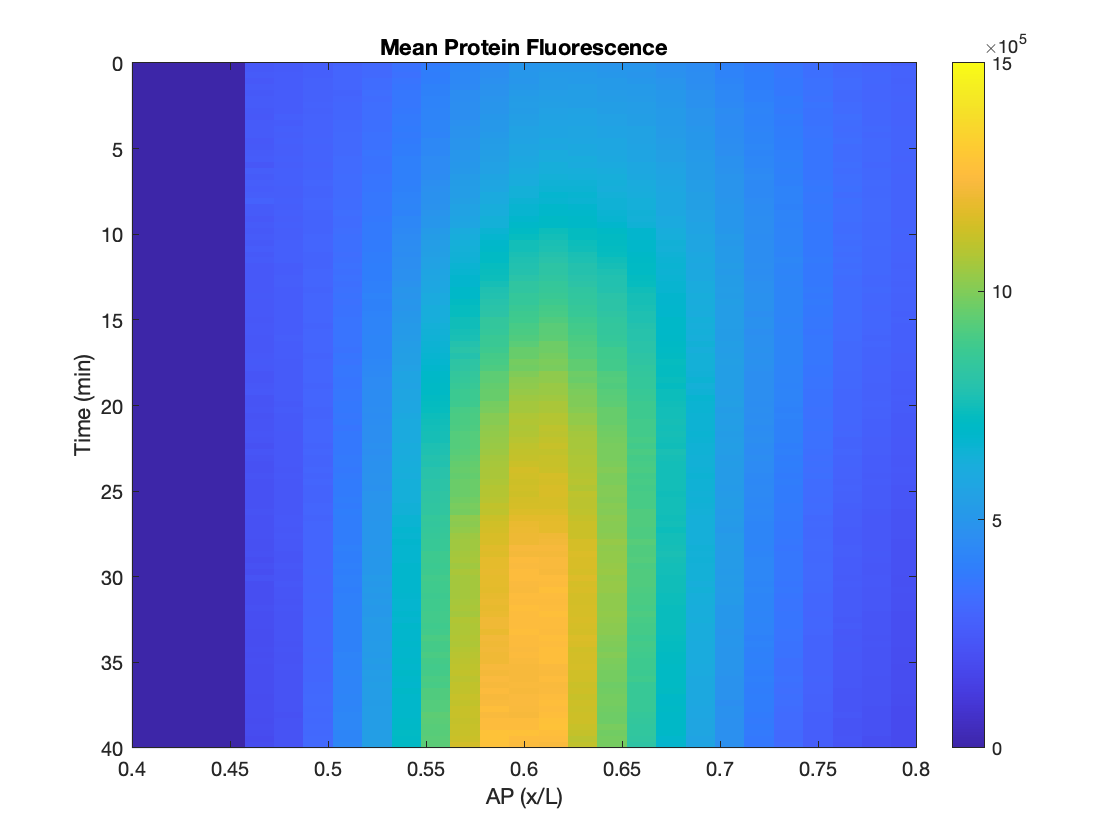

data_plot = data.nuclei.MeanVectorAP(start_frame:final_frame,:);
%data_plot = data.nuclei.MeanVectorAP(start_frame:final_frame,:)/correction_factor;
% Embryo 7/10
%data_plot(1:switch_frame-1) = data_plot(1:switch_frame-1)/correction_factor_1;
%data_plot(switch_frame:end) = data_plot(switch_frame:end)/correction_factor_2;

MeanNucleiFig = figure;
imagesc(APbinID,Time,data_plot);
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 40])
colorbar
caxis([0 15E5])
title('Mean Protein Fluorescence')
saveas(MeanNucleiFig,[FigPath '/MeanProtein_fluo.pdf' ]);